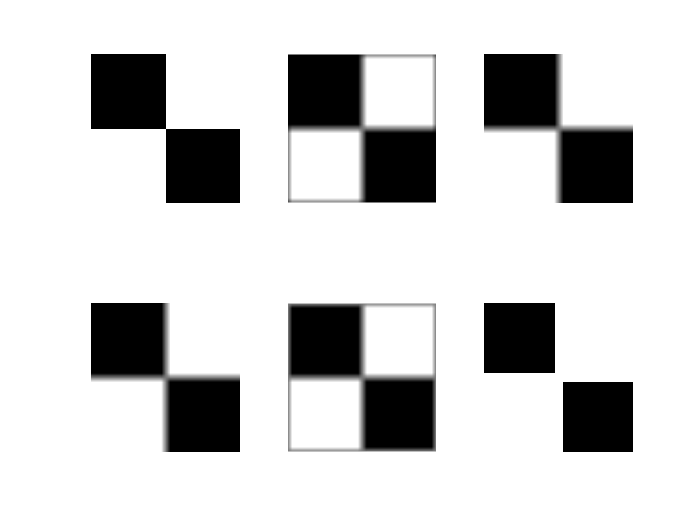

clear;
clc;
f=imread('Fig0216(a).tif');
f=im2double(f);%将512x512unit8类型图像转化为double类型,得到的结果精度更高
figure;
subplot(2,3,1);
imshow(f,[]);
w=ones(31);%采用31x31的滤波器
gd=imfilter(f,w);%使用了默认的边界选项，用0对边界进行填充，处理后图像灰白边缘被模糊，且图像边缘出现黑框
subplot(2,3,2);
imshow(gd,[]);
gr=imfilter(f,w,'replicate');%图像的大小通过复制外边界的值来扩展
subplot(2,3,3);
imshow(gr,[]);
gs=imfilter(f,w,'symmetric');%图像大小通过沿自身的边界进行镜像映射扩展
subplot(2,3,4);
imshow(gs,[]);
gc=imfilter(f,w,'circular');%图像的大小通过将图像作为二维周期函数的一个周期来扩展
subplot(2,3,5);
imshow(gc,[]);
f8=im2uint8(f);
g8r=imfilter(f8,w,'replicate');%裁剪发生数据丢失，输出超过整型类型的范围的元素将被截去，小数部分四舍五入。
subplot(2,3,6);
imshow(g8r,[]);